# Townsend Discharges in Planetary Atmospheres

clearvars

## Breakdown Fields & Fit Coefficient Initial Guess

### Solve

P(1) = Scaling_N('Earth','none');

 
 Func-count    x          f(x)             Procedure
    2          806400      -2.95881        initial
    3          806903      -2.97493        interpolation
    4          806903      -2.97493        bisection
    5          809421      -3.04209        interpolation
    6     2.62244e+06      -496.474        bisection
    7     2.62244e+06      -496.474        bisection
    8     2.97716e+06      -234.662        interpolation
    9     3.22101e+06       113.971        interpolation
   10      3.1413e+06      -16.6656        interpolation
   11     3.15147e+06       -0.8064        interpolation
   12      3.1521e+06        0.2688        interpolation
 
Zero found in the interval [806400, 8.064e+06]


P(2) = Scaling_N('Mars','none');

 
 Func-count    x          f(x)             Procedure
    2         5665.89    -0.0541041        initial
    3         5671.02    -0.0545572        interpolation
    4         5671.02    -0.0545572        bisection
    5         5683.34    -0.0554824        interpolation
    6         5683.34    -0.0554824        bisection
    7         5762.85    -0.0622792        interpolation
    8         12093.5      -1.33016        bisection
    9         15258.8      0.985865        bisection
   10         13911.4     -0.540148        interpolation
   11         14388.4     -0.105763        interpolation
   12         14493.2    0.00566589        interpolation
   13         14487.9             0        interpolation
 
Zero found in the interval [5665.89, 56658.9]


P(3) = Scaling_N('Venus','none');

 
 Func-count    x          f(x)             Procedure
    2     2.74847e+07      -222.332        initial
    3     2.75061e+07      -223.614        interpolation
    4     2.75061e+07      -223.614        bisection
    5     2.75579e+07      -227.461        interpolation
    6     2.75579e+07      -227.461        bisection
    7     2.79055e+07      -253.564        interpolation
    8     5.86363e+07      -6356.29        bisection
    9     7.40017e+07       3930.31        bisection
   10     6.81309e+07      -2464.46        interpolation
   11     7.03934e+07      -430.593        interpolation
   12     7.08251e+07       27.4847        interpolation
   13     7.07992e+07             0        interpolation
 
Zero found in the interval [2.74847e+07, 2.74847e+08]


P(4) = Scaling_N('Titan','none');

 
 Func-count    x          f(x)             Procedure
    2     3.42723e+06   -0.00450197        initial
    3     3.42791e+06   -0.00538657        interpolation
    4     3.42791e+06   -0.00538657        bisection
    5      3.4286e+06   -0.00538657        interpolation
    6      3.4286e+06   -0.00538657        bisection
    7     3.42928e+06   -0.00453854        interpolation
    8     3.43295e+06   -0.00459279        interpolation
    9     3.43295e+06   -0.00459279        bisection
   10     3.43548e+06   -0.00462932        interpolation
   11     5.36081e+06      -0.20472        bisection
   12     5.36081e+06      -0.20472        bisection
   13     5.63586e+06     -0.188269        interpolation
   14     5.97967e+06    -0.0107386        bisection
   15     5.99677e+06    0.00514084        interpolation
   16     5.99124e+06  -0.000228482        interpolation
   17     5.99124e+06  -0.000228482        interpolation
 
Zero found in the interval [3.42723e+06, 3.42723e+07]


### Solution

P.Ek_N

ans = 117.2655

ans = 76.7112

ans = 77.2786

ans = 52.4439

P.Ek

ans = 3.1521e+06

ans = 1.4488e+04

ans = 7.0799e+07

ans = 5.9912e+06

P.A

ans = 7.3757e-21

ans = 2.6207e-20

ans = 2.6941e-20

ans = 1.0493e-20

P.B

ans = -596.8498

ans = -594.3072

ans = -602.4930

ans = -723.3514

## Scaling laws

t = tiledlayout(2,1);
t.TileSpacing = 'tight';
t.Padding = 'loose';
for k = 1:numel(P)

### Effective Ionization

    disp(P(k).name);
    ax   = nexttile(t,1);
    E_N  = P(k).E_N;
    aa_N = P(k).aa_N;
    opts1 = fitoptions('Method','NonlinearLeastSquares',...
        'Normalize','off',...
        'Lower',[-inf 0], ...
        'StartPoint', [ P(k).A -P(k).B ],...
        'DiffMinChange', 1e-21,...
        'TolFun',1e-25,...
        'TolX',1);
    ft1 = fittype('A*exp(-B/x)',...
        'independent','x',...
        'coefficients', {'A','B'},...
        'options',opts1);
    cfit1  = fit(E_N,aa_N, ft1)
    P(k).A = cfit1.A;
    P(k).B = -cfit1.B;
    aaP_N  = predint(cfit1,E_N,.95,'functional','on');
    aaF_N  = feval(cfit1,E_N);
    cnd1   = aaP_N(:,1).*aaP_N(:,2)>0;
    Eb_N   = [E_N(cnd1)' fliplr(E_N(cnd1)')]; % bounded interval of confidence (x-axis)
    aab_N  = [aaP_N(cnd1,1)' fliplr(aaP_N(cnd1,2)')]; % bounded interval of confidence (y-axis)

    hold on
    plot(E_N,aaF_N, P(k).ls        ,'DisplayName',[P(k).name,' $\tilde{\alpha}/N$'])
    plot(E_N,aa_N ,[P(k).ls(1),'.'],'DisplayName',[P(k).name,' $\alpha/N$'])
    fill(Eb_N,aab_N,P(k).ls,'FaceAlpha',.25,'EdgeColor','none','DisplayName','95\% confidence range')
    hold off
    lgd              = legend();
    lgd.NumColumns   = 2;
    lgd.Interpreter  = 'latex';
    lgd.Box          = "off";
    lgd.Location     = "best";
    ax.XScale        = 'lin';
    ax.YScale        = 'log';
    ax.YTick         = logspace(-30,-20,6);
    ax.XLabel.String = 'E/N (Td)';
    ax.YLabel.String = '\alpha/N (m^2)';
    ax.TickDir       = 'out';
    ax.XMinorTick    = 'on';
    ax.YMinorTick    = 'on';

### Mobility

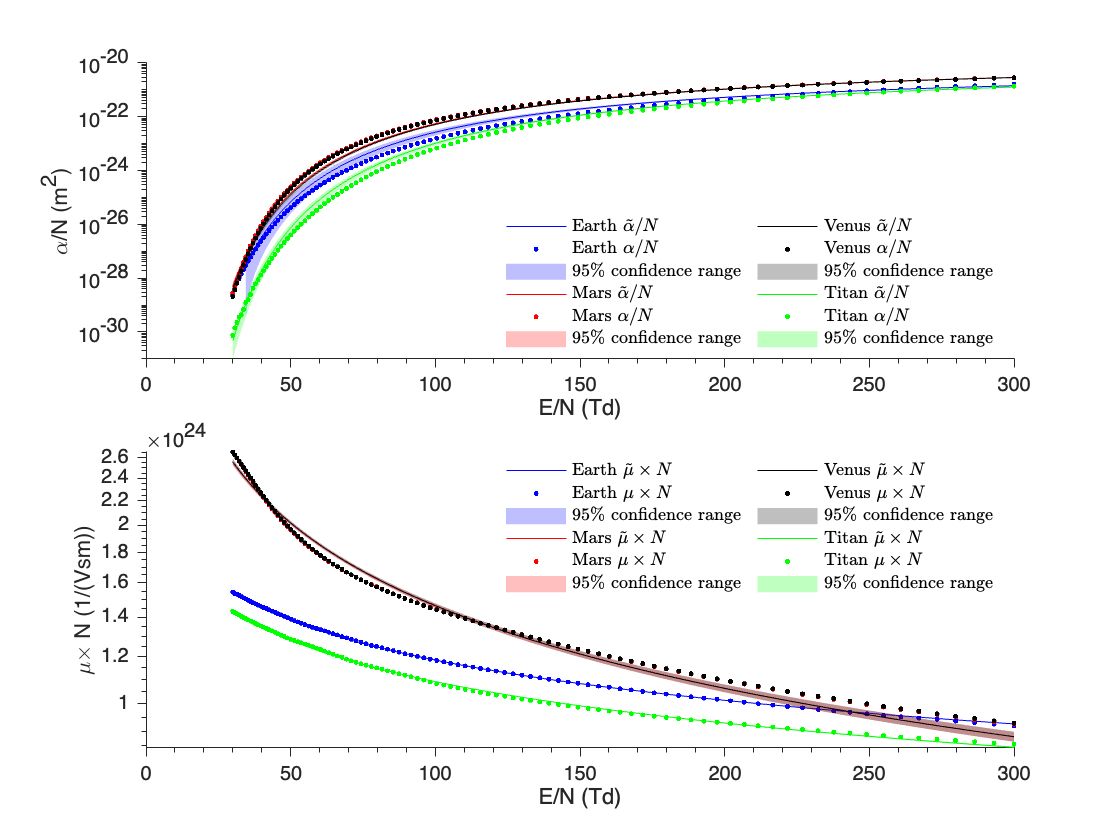

Earth


cfit1 =      General model:
     cfit1(x) = A*exp(-B/x)
     Coefficients (with 95% confidence bounds):
       A =   1.044e-20  (9.098e-21, 1.178e-20)
       B =       596.8  (565.3, 628.4)

cfit2 =      General model:
     cfit2(x) = C*x^D
     Coefficients (with 95% confidence bounds):
       C =       3.352  (3.34, 3.365)
       D =     -0.2257  (-0.2265, -0.2248)

Mars


cfit1 =      General model:
     cfit1(x) = A*exp(-B/x)
     Coefficients (with 95% confidence bounds):
       A =   2.112e-20  (2.045e-20, 2.18e-20)
       B =       594.3  (586.5, 602.2)

cfit2 =      General model:
     cfit2(x) = C*x^D
     Coefficients (with 95% confidence bounds):
       C =       12.32  (11.84, 12.81)
       D =     -0.4627  (-0.4721, -0.4533)

Venus


cfit1 =      General model:
     cfit1(x) = A*exp(-B/x)
     Coefficients (with 95% confidence bounds):
       A =   2.145e-20  (2.069e-20, 2.221e-20)
       B =       602.5  (593.8, 611.2)

cfit2 =      General model:
     cfit2(x) = C*x^D
     Coefficients (with 95% confidence bounds):
       C =       12.38  (11.89, 12.87)
       D =     -0.4635  (-0.4729, -0.454)

Titan


cfit1 =      General model:
     cfit1(x) = A*exp(-B/x)
     Coefficients (with 95% confidence bounds):
       A =   1.425e-20  (1.304e-20, 1.546e-20)
       B =       723.4  (701.8, 744.9)

cfit2 =      General model:
     cfit2(x) = C*x^D
     Coefficients (with 95% confidence bounds):
       C =       3.175  (3.153, 3.196)
       D =      -0.232  (-0.2336, -0.2305)

    ax=nexttile(t,2);
    uxN = P(k).uxN*1e-24;

    opts2 = fitoptions('Method','NonlinearLeastSquares',...
        'Normalize','off',...
        'StartPoint',[P(k).C*1e-24 P(k).D]);
    ft2 = fittype('C*x^D',...
        'independent','x',...
        'coefficients', {'C','D'},...
        'options',opts2);
    cfit2 = fit(E_N,uxN, ft2)
    P(k).C = cfit2.C*1e24;
    P(k).D = cfit2.D;
    
    uPxN  = predint(cfit2,E_N,.95,'functional','on');
    uFxN  = feval(cfit2,E_N);
    cnd2  = uPxN(:,1).*uPxN(:,2)>0;
    Eb_N  = [E_N(cnd2)' fliplr(E_N(cnd2)')];
    ubxN  = [uPxN(cnd2,1)' fliplr(uPxN(cnd2,2)')];

    hold on
    plot(E_N ,uFxN*1e24,P(k).ls,'DisplayName',[P(k).name,' $\tilde{\mu}\times N$'])
    plot(E_N ,uxN *1e24,[P(k).ls(1),'.'],'DisplayName',[P(k).name,' $\mu\times N$'])
    fill(Eb_N,ubxN*1e24,P(k).ls,'FaceAlpha',.25,'EdgeColor','none','DisplayName','95\% confidence range')
    hold off

    lgd = legend();
    lgd.NumColumns = 2;
    lgd.Interpreter = 'latex';
    lgd.Box = "off";
    lgd.Location = "best";
    %ax.XTick = [30:10:90 100:100:300];
    % ax.YTick = (0:.5:3);
    ax.XScale = 'linear';
    ax.YScale = 'log';
    ax.XLabel.String = 'E/N (Td)';
    ax.YLabel.String = '\mu\times N (1/(Vsm))';
    ax.TickDir = 'out';
    ax.XMinorTick = 'on';
    ax.YMinorTick = 'on';
end

## Theoretical Coefficients in pressure

### A, B, D, γ from Scaling_N

pa = logspace(2,-2,51); % cm Torr
pd = logspace(3,-2,121); % cm Torr
pd_min(1) = 1; % cm.Torr
pd_min(2) = .25; % cm.Torr
for k=1:numel(P)
    P(k).Ap   =  P(k).A   *(101325      )/(760*100*1.3806e-23*P(k).T_g); % cm-1/Torr
    P(k).Bp   = -P(k).B   *(101325*1e-21)/(760*100*1.3806e-23*P(k).T_g); % V/cm/Torr
    P(k).Ek_p =  P(k).Ek_N*(101325*1e-21)/(760*100*1.3806e-23*P(k).T_g);
    P(k).gg   = 1e-2;% double(1./(exp(P(k).Ap.*pd_min(k)*exp(-1)) - 1));
    [P(k).Ca,P(k).Cy,P(k).S] = SSC(P(k),pa,pd,'noplots');
end

    @(E_p_a,pd)-log(1.01e+2)+pd.*exp((-2.110963460627377e+2)./E_p_a).*3.692308422606501

    @(r,E_p_a,pd)E_p_a.*pd

    @(E_p_a,pd)-log(1.01e+2)+pd.*exp((-2.110963460627377e+2)./E_p_a).*3.692308422606501

    @(r,E_p_a,pa,pd)E_p_a.*pa.*log(pd./pa+1.0)

    @(E_p_a,pa,pd)sqrt(E_p_a).*(erf((6.093969308449219e+7.*1.0./sqrt(E_p_a).*(pd./pa+1.0))./4.194304e+6)-erf((6.093969308449219e+7.*1.0./sqrt(E_p_a))./4.194304e+6))-(6.093969308449219e+7.*1.0./sqrt(pi).*log((pd./pa+1.0).^4.513245188772559e-1.*1.01e+2).*1.291433714701744e-7)./pa

    @(r,E_p_a,pa,pd)-E_p_a.*pa.*(1.0./(pd./pa+1.0)-1.0)



    @(E_p_a,pd)-log(1.01e+2)+pd.*exp((-2.482323203240986e+2)./E_p_a).*8.823275616274534

    @(r,E_p_a,pd)E_p_a.*pd

    @(E_p_a,pd)-log(1.01e+2)+pd.*exp((-2.482323203240986e+2)./E_p_a).*8.823275616274534

    @(r,E_p_a,pa,pd)E_p_a.*pa.*log(pd./pa+1.0)

    @(E_p_a,pa,pd)sqrt(E_p_a).*(erf((6.608289613340663e+7.*1.0./sqrt(E_p_a).*(pd./pa+1.0))./4.194304e+6)-erf((6.608289613340663e+7.*1.0./sqrt(E_p_a))./4.194304e+6))-(6.608289613340663e+7.*1.0./sqrt(pi).*log((pd./pa+1.0).^9.25363419431859e-1.*1.01e+2).*5.404309906443348e-8)./pa

    @(r,E_p_a,pa,pd)-E_p_a.*pa.*(1.0./(pd./pa+1.0)-1.0)



    @(E_p_a,pd)-log(1.01e+2)+pd.*exp((-7.894410106225004e+1)./E_p_a).*2.810337478512892

    @(r,E_p_a,pd)E_p_a.*pd

    @(E_p_a,pd)-log(1.01e+2)+pd.*exp((-7.894410106225004e+1)./E_p_a).*2.810337478512892

    @(r,E_p_a,pa,pd)E_p_a.*pa.*log(pd./pa+1.0)

    @(E_p_a,pa,pd)sqrt(E_p_a).*(erf((5.931641601515722e+6.*5.270292805900411e+7.*1.0./sqrt(E_p_a).*(pd./pa+1.0))./3.5184372088832e+13)-erf((5.931641601515722e+6.*5.270292805900411e+7.*1.0./sqrt(E_p_a))./3.5184372088832e+13))-(5.931641601515722e+6.*5.270292805900411e+7.*1.0./sqrt(pi).*log((pd./pa+1.0).^9.269195089847702e-1.*1.01e+2).*2.022654549335017e-14)./pa

    @(r,E_p_a,pa,pd)-E_p_a.*pa.*(1.0./(pd./pa+1.0)-1.0)



    @(E_p_a,pd)-log(1.01e+2)+pd.*exp((-7.439074522706059e+2)./E_p_a).*1.465249060835868e+1

    @(r,E_p_a,pd)E_p_a.*pd

    @(E_p_a,pd)-log(1.01e+2)+pd.*exp((-7.439074522706059e+2)./E_p_a).*1.465249060835868e+1

    @(r,E_p_a,pa,pd)E_p_a.*pa.*log(pd./pa+1.0)

    @(E_p_a,pa,pd)sqrt(E_p_a).*(erf((2.965820800757861e+6.*8.089177430422705e+7.*1.0./sqrt(E_p_a).*(pd./pa+1.0))./8.796093022208e+12)-erf((2.965820800757861e+6.*8.089177430422705e+7.*1.0./sqrt(E_p_a))./8.796093022208e+12))-(2.965820800757861e+6.*8.089177430422705e+7.*1.0./sqrt(pi).*log((pd./pa+1.0).^4.640323339747354e-1.*1.01e+2).*1.551774927011549e-14)./pa

    @(r,E_p_a,pa,pd)-E_p_a.*pa.*(1.0./(pd./pa+1.0)-1.0)



P(:).Ap

ans = 3.6923

ans = 8.8233

ans = 2.8103

ans = 14.6525

P(:).Bp

ans = 211.0963

ans = 248.2323

ans = 78.9441

ans = 743.9075

P(:).D

ans = -0.2257

ans = -0.4627

ans = -0.4635

ans = -0.2320

### A, B, γ from (Raizer, 1991)

Theory w/ Raizer coeff

P(1).R91.A = 15; % 1/(_cm_Torr) R91
P(1).R91.B = 365; % _V/(_cm_Torr) R91
P(2).R91.A = 20; % 1/(_cm_Torr) R91
P(2).R91.B = 466; % _V/(_cm_Torr) R91
P(3).R91.A = 20; % 1/(_cm_Torr) R91
P(3).R91.B = 466; % _V/(_cm_Torr) R91
P(4).R91.A = 12; % 1/(_cm_Torr) R91
P(4).R91.B = 342; % _V/(_cm_Torr) R91
%{
for k=1:numel(P)
    P(k).Ap = P(k).R91.A; % cm-1/Torr
    P(k).Bp = P(k).R91.B; % V/cm/Torr
    P(k).gg = double(1./(exp(P(k).Ap.*pd_min(k)*exp(-1)) - 1));
    [P(k).Ca,P(k).Cy,P(k).S] = SSC(P(k),pa,pd,'noplots');
end
%}
for k=1:numel(P)
    A = P(k).R91.A;
    B = P(k).R91.B;
    gg = P(k).gg;
    V{k}.cr = B*pd./log(A*pd/log(1+1/gg));
    E{k}.cr_p = B./log(A*pd/log(1+1/gg));
end
clear A B gg ax

## Data

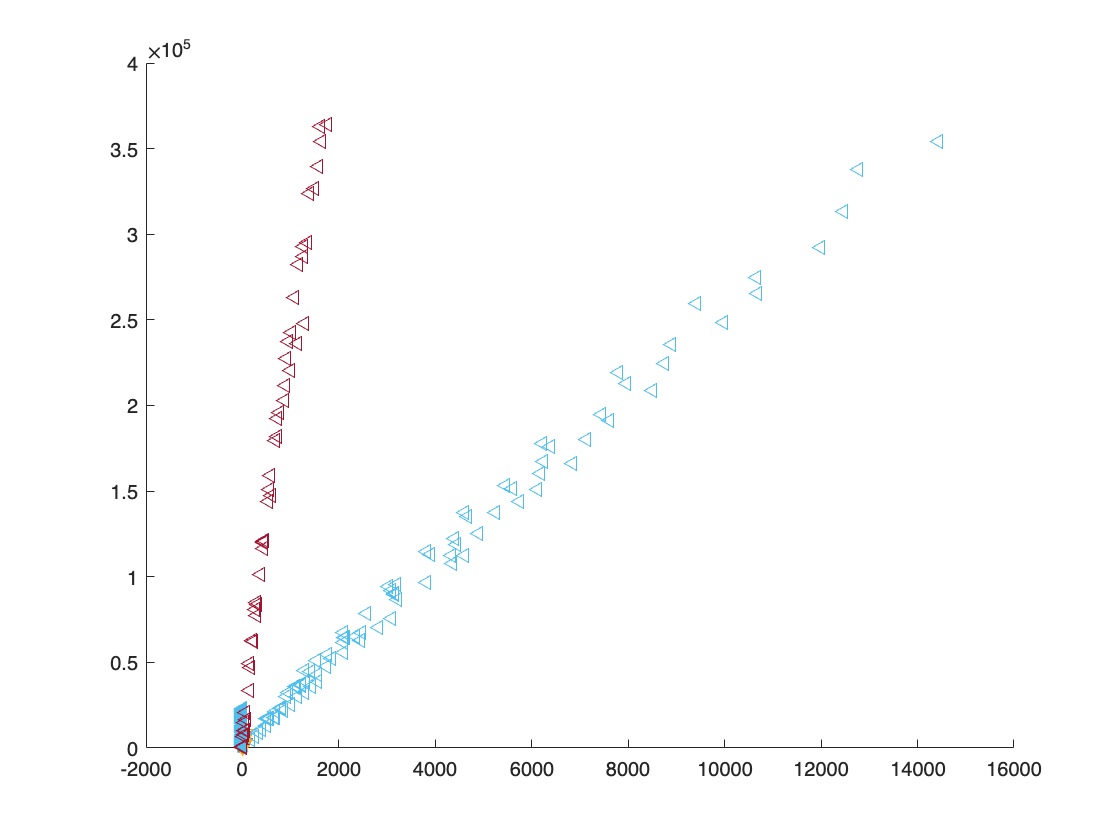

data = 1×15 struct array with fields:
    source
    lgd
    geometry
    gas
    marker
    color
    pd_Vcr
    pd_Ecr_p


% [CO2,~,N2,Earth,Mars] = loadData()
data = loadData()

for j = 1:numel(data)
    if strcmp(data(j).gas,'Mars')
        data(j).relevance = {'Mars'};
    elseif strcmp(data(j).gas,'Earth')
        data(j).relevance = {'Earth'};
    elseif strcmp(data(j).gas,'$\rm CO_2$')
        data(j).relevance = {'Mars', 'Venus'};
    elseif strcmp(data(j).gas,'$\rm N_2$')
        data(j).relevance = {'Earth', 'Titan'};
    elseif strcmp(data(j).gas,'He')
        data(j).relevance = {'Jupiter', 'Saturn'};
    end
end

## Updated Theory Curves

% clearvars
% load

### Format

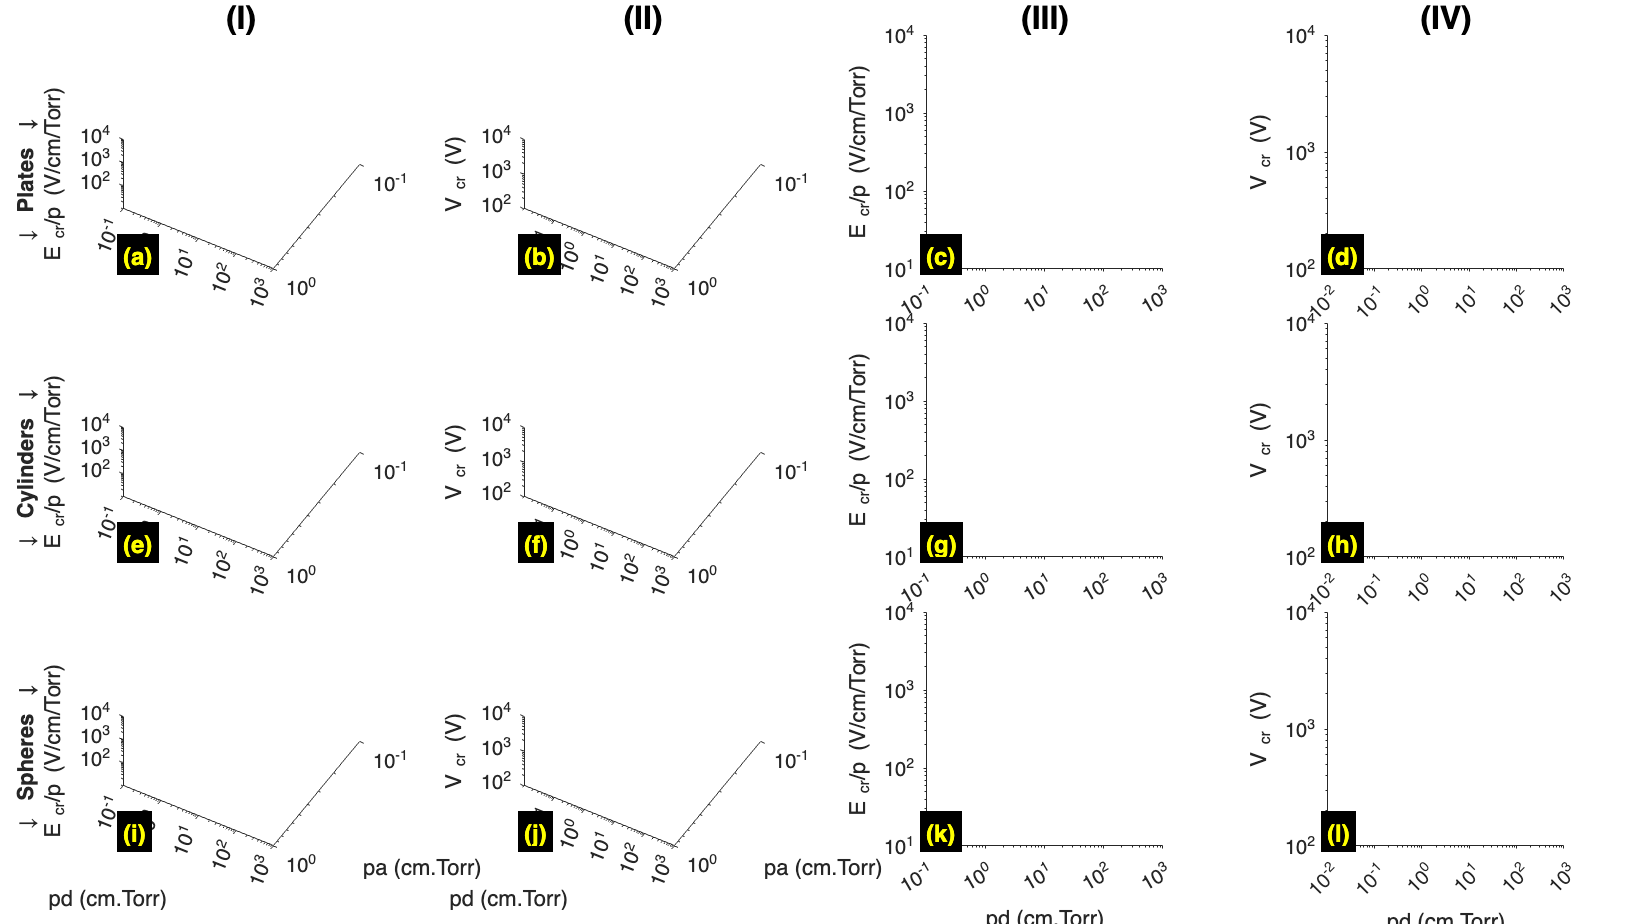

idx=[];
for k = -1:2
    idx(end+1) = find(pa<=10^k,1);
end
for k=1:numel(P)
    if strcmp(P(k).name,'Mars')
        P(k).color = 'r';
    elseif strcmp(P(k).name,'Earth')
        P(k).color = 'b';
    elseif strcmp(P(k).name,'Venus')
        P(k).color = 'm';
    elseif strcmp(P(k).name,'Titan')
        P(k).color = [0,128,0]/255;
    end
end
LS = {':','-.','--','-'};

clf
abc = 'abcdefghijklmnopqrstuvwxyz';
col = {'(I)','(II)','(III)','(IV)'};
m = 3;
n = 4;
for k=1:numel(P)
    hf(k) = figure('Name',P(k).name);
    hf(k).Units = "inches";
    hf(k).OuterPosition = [0 0 16 9];
    ht(k) = tiledlayout(hf(k),m,n);
    ht(k).TileSpacing = 'tight';
    ht(k).Padding = "compact";
    for i = 1:(m*n)
        ax(k,i) = nexttile(i);
    end
    ht(k).Title.String = '';%P(k).name;
end

geom = {'\downarrow\bf Plates \downarrow ','\downarrow\bf Cylinders \downarrow ','\downarrow\bf Spheres \downarrow '};

for k = 1:numel(P)
    for i = 1:(m*n)
        ax(k,i).TickDir       = 'out';
        ax(k,i).XMinorTick    = 'on';
        ax(k,i).XScale        = 'log';
        if i>2*n
            ax(k,i).XLabel.String = 'pd (cm.Torr)';
        else
            ax(k,i).XLabel.String = '';
        end

        if ismember(i,[3 4 7 8 11 12])
            ax(k,i).XTick         = logspace(-2,4,7);
            ax(k,i).YTick         = logspace(1,6,6);
            ax(k,i).YMinorTick    = 'on';
            ax(k,i).YScale        = 'log';
            if rem(i,2)==0
                ax(k,i).XLim          = [.01 1e3];
                ax(k,i).YLabel.String = 'V_{\rm cr} (V)';
                ax(k,i).YLim          = [1e2 1e4];
            else
                ax(k,i).XLim          = [.1 1e3];
                ax(k,i).YLabel.String = 'E_{\rm cr}/p (V/cm/Torr)';
                ax(k,i).YLim          = [1e1 1e4];
            end
        else
            ax(k,i).CLim          = [100 5000];
            ax(k,i).Colormap      = colormap("turbo");
            ax(k,i).View          = [-30,-60];
            ax(k,i).XTick         = logspace(-1,3,5);
            ax(k,i).YTick         = logspace(-1,3,5);
            ax(k,i).ZTick         = logspace(2,4,3);
            ax(k,i).YMinorTick    = 'on';
            ax(k,i).ZMinorTick    = 'on';
            ax(k,i).YScale        = 'log';
            ax(k,i).ZScale        = 'log';
            if i>2*n
                ax(k,i).YLabel.String = 'pa (cm.Torr)';
            else
                ax(k,i).YLabel.String = '';
            end
            if rem(i,2)==0
                ax(k,i).XLim          = [.01 1e3];
                ax(k,i).ZLabel.String = 'V_{\rm cr} (V)';
                ax(k,i).ZLim          = [1e2 1e4];
            else
                ax(k,i).XLim          = [.1 1e3];
                switch i
                    case 1
                        ax(k,i).ZLabel.String = {geom{1},'E_{\rm cr}/p (V/cm/Torr)'};
                    case 5
                        ax(k,i).ZLabel.String = {geom{2},'E_{\rm cr}/p (V/cm/Torr)'};
                    case 9
                        ax(k,i).ZLabel.String = {geom{3},'E_{\rm cr}/p (V/cm/Torr)'};                    
                end                
                ax(k,i).ZLim          = [1e1 1e4];
            end
        end
        ax(k, i).Title.String              = ['(',abc(i),')'];
        ax(k, i).Title.BackgroundColor     = [0 0 0];
        ax(k, i).Title.Color               = 'y';
        ax(k, i).Title.Units               = "normalized";
        ax(k, i).Title.Position            = [0,0];
        ax(k, i).Title.HorizontalAlignment = 'left';
        ax(k, i).Title.VerticalAlignment   = 'bottom';
        ax(k, i).Title.FontSize            = 12;
        if i<=4
            text(ax(k,i),...
                'Units','normalized',...
                'VerticalAlignment','bottom',...
                'HorizontalAlignment','center',...
                'Position',[.5 1],...
                'FontSize',16,...
                'FontWeight','bold',...
                'String',col{i});
        end
    end
end
hold(ax,"on");

for k = 1:4
    disp(P(k).name)

### High-Field Regions

    for j=3:n:(m*n)
        patch(ax(k,j),...
            [ax(k,j).XLim(1) ax(k,j).XLim(2) ax(k,j).XLim(2) ax(k,j).XLim(1)],...
            [10*P(k).Ek_p    10*P(k).Ek_p    ax(k,j).YLim(2) ax(k,j).YLim(2)],...
            0,...
            'FaceColor',[.1 .1 .1],...
            'EdgeColor','none',...
            'FaceAlpha', .25)
    end
    for j=4:n:(m*n)
        patch(ax(k,j),...
            [pd,fliplr(pd)],...
            [10*P(k).Ek_p*pd,ones(size(pd))*ax(k,j).YLim(2)],...
            0,...
            'FaceColor',[.1 .1 .1],...
            'EdgeColor','none',...
            'FaceAlpha', .25)
    end

### Surface plots

    mesh( ax(k, 1),pd,pa,P(k).Ca.Ecr_pa)
    meshc(ax(k, 2),pd,pa,P(k).Ca.Vcr)
    mesh( ax(k, 5),pd,pa,P(k).Cy.Ecr_pa)
    meshc(ax(k, 6),pd,pa,P(k).Cy.Vcr)
    mesh( ax(k, 9),pd,pa,P(k).S.Ecr_pa)
    meshc(ax(k,10),pd,pa,P(k).S.Vcr)
    ax(k, 1).View = [-30 -30];
    ax(k, 5).View = [-30 -30];
    ax(k, 9).View = [-30 -30];

### Updated Theory Line Plots

    hp{k} = [];
    % New theory
    for i=1:numel(idx)
        hp{k}(end+1) = plot(ax(k,3),pd,P(k).Ca.Ecr_pa(idx(i),:),....
            'LineStyle',LS{i},'Color',P(k).color,'DisplayName',[P(k).name,', pa = ',num2str(pa(idx(i)),'%4.1f'), ' $\rm (cm\cdot Torr)$']);
        plot(ax(k,4),pd,P(k).Ca.Vcr(idx(i),:),...
            'LineStyle',LS{i},'Color',P(k).color,'DisplayName',[P(k).name,', pa = ',num2str(pa(idx(i)),'%4.1f'), ' $\rm (cm\cdot Torr)$']);
        plot(ax(k,7),pd,P(k).Cy.Ecr_pa(idx(i),:),...
            'LineStyle',LS{i},'Color',P(k).color,'DisplayName',[P(k).name,', pa = ',num2str(pa(idx(i)),'%4.1f'), ' $\rm (cm\cdot Torr)$']);
        plot(ax(k,8),pd,P(k).Cy.Vcr(idx(i),:),...
            'LineStyle',LS{i},'Color',P(k).color,'DisplayName',[P(k).name,', pa = ',num2str(pa(idx(i)),'%4.1f'), ' $\rm (cm\cdot Torr)$']);
        plot(ax(k,11),pd,P(k).S.Ecr_pa(idx(i),:),...
            'LineStyle',LS{i},'Color',P(k).color,'DisplayName',[P(k).name,', pa = ',num2str(pa(idx(i)),'%4.1f'), ' $\rm (cm\cdot Torr)$']);
        plot(ax(k,12),pd,P(k).S.Vcr(idx(i),:),...
            'LineStyle',LS{i},'Color',P(k).color,'DisplayName',[P(k).name,', pa = ',num2str(pa(idx(i)),'%4.1f'), ' $\rm (cm\cdot Torr)$']);
    end

### Raizer Theory Line Plots

    hp{k}(end+1) = plot(ax(k,3),pd,E{k}.cr_p,...
        'Color',P(k).color,'Marker','.','LineStyle','none','DisplayName',[P(k).name,' (Raizer, 1991)']);
    plot(ax(k,4),pd,V{k}.cr  ,...
        'Color',P(k).color,'Marker','.','LineStyle','none','DisplayName',[P(k).name,' (Raizer, 1991)']);

### Experimental Data

    for j=1:numel(data)
        DN{j} = [data(j).gas,' (',data(j).lgd,')'];
        switch P(k).name
            case data(j).relevance
                if ~isempty(data(j).pd_Ecr_p)
                    if     strcmp(data(j).geometry,'Plates')
                        hp{k}(end+1) = plot(ax(k,3),data(j).pd_Ecr_p(:,1),data(j).pd_Ecr_p(:,2),...
                            'Color',data(j).color,'Marker',data(j).marker,'LineStyle','none','Displayname', DN{j});
                    elseif strcmp(data(j).geometry,'Cylinders')
                        hp{k}(end+1) = plot(ax(k,7),data(j).pd_Ecr_p(:,1),data(j).pd_Ecr_p(:,2),...
                            'Color',data(j).color,'Marker',data(j).marker,'LineStyle','none','Displayname', DN{j});
                    elseif strcmp(data(j).geometry,'Spheres')
                        hp{k}(end+1) = plot(ax(k,11),data(j).pd_Ecr_p(:,1),data(j).pd_Ecr_p(:,2),...
                            'Color',data(j).color,'Marker',data(j).marker,'LineStyle','none','Displayname', DN{j});
                    end
                end
                if ~isempty(data(j).pd_Vcr)
                    if     strcmp(data(j).geometry,'Plates')
                        hp{k}(end+1) = plot(ax(k,4),data(j).pd_Vcr(:,1),data(j).pd_Vcr(:,2),...
                            'Color',data(j).color,'Marker',data(j).marker,'LineStyle','none','Displayname', DN{j});
                    elseif strcmp(data(j).geometry,'Cylinders')
                        hp{k}(end+1) = plot(ax(k,8),data(j).pd_Vcr(:,1),data(j).pd_Vcr(:,2),...
                            'Color',data(j).color,'Marker',data(j).marker,'LineStyle','none','Displayname', DN{j});
                    elseif strcmp(data(j).geometry,'Spheres')
                        hp{k}(end+1) = plot(ax(k,12),data(j).pd_Vcr(:,1),data(j).pd_Vcr(:,2),...
                            'Color',data(j).color,'Marker',data(j).marker,'LineStyle','none','Displayname', DN{j});
                    end
                end
        end
    end
%     P(k).name
end

Earth
Mars
Venus
Titan


### Legend

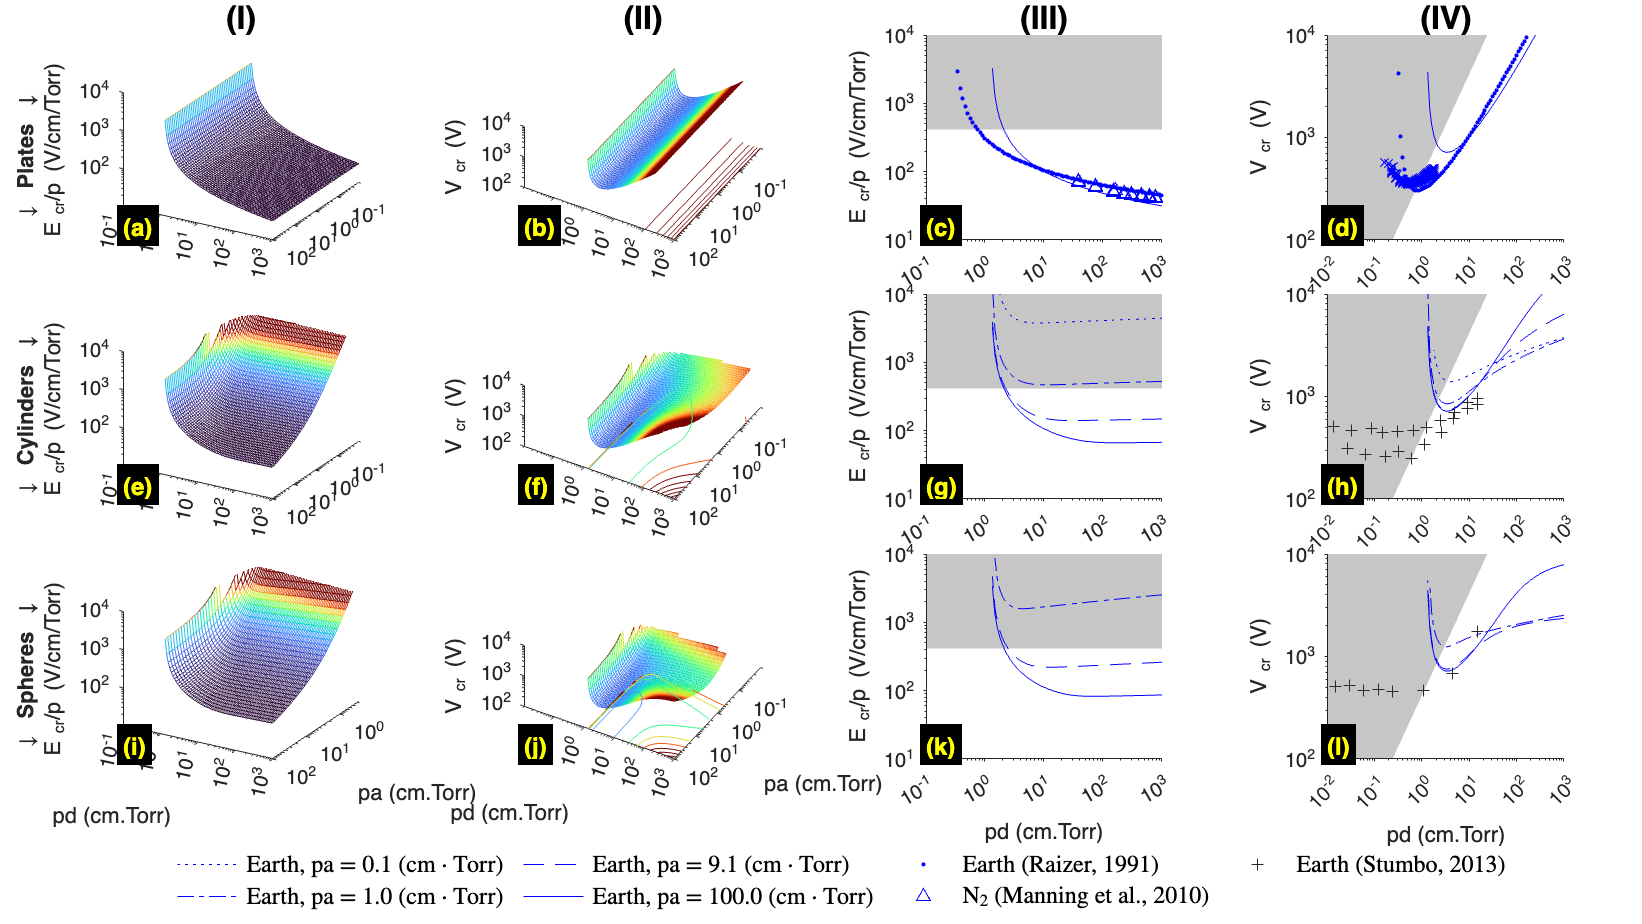

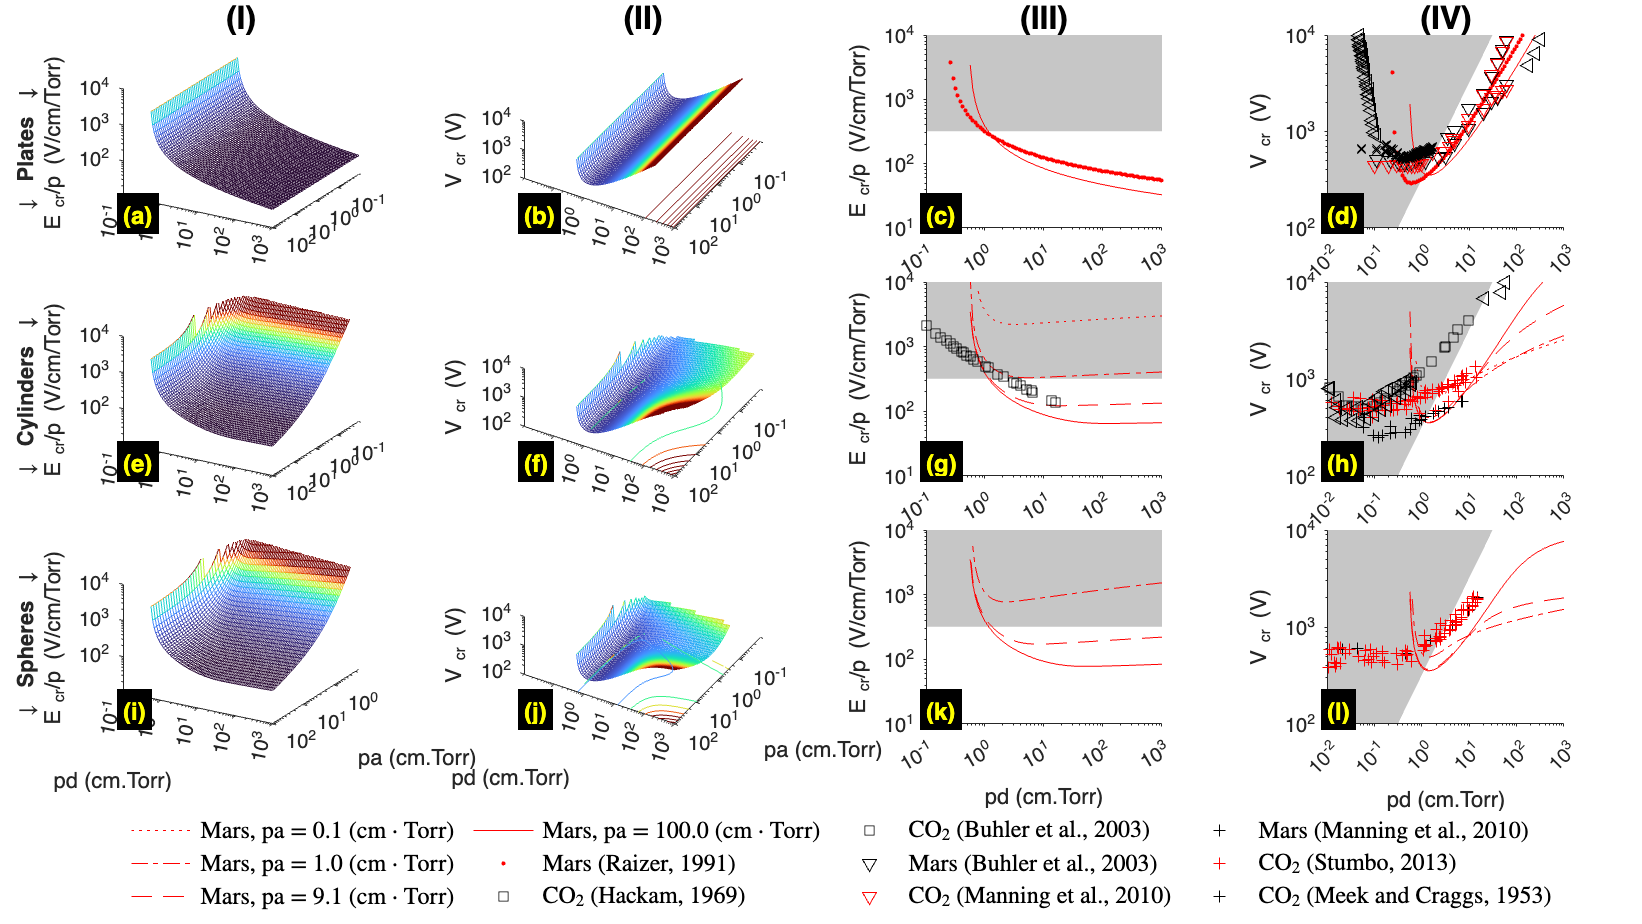

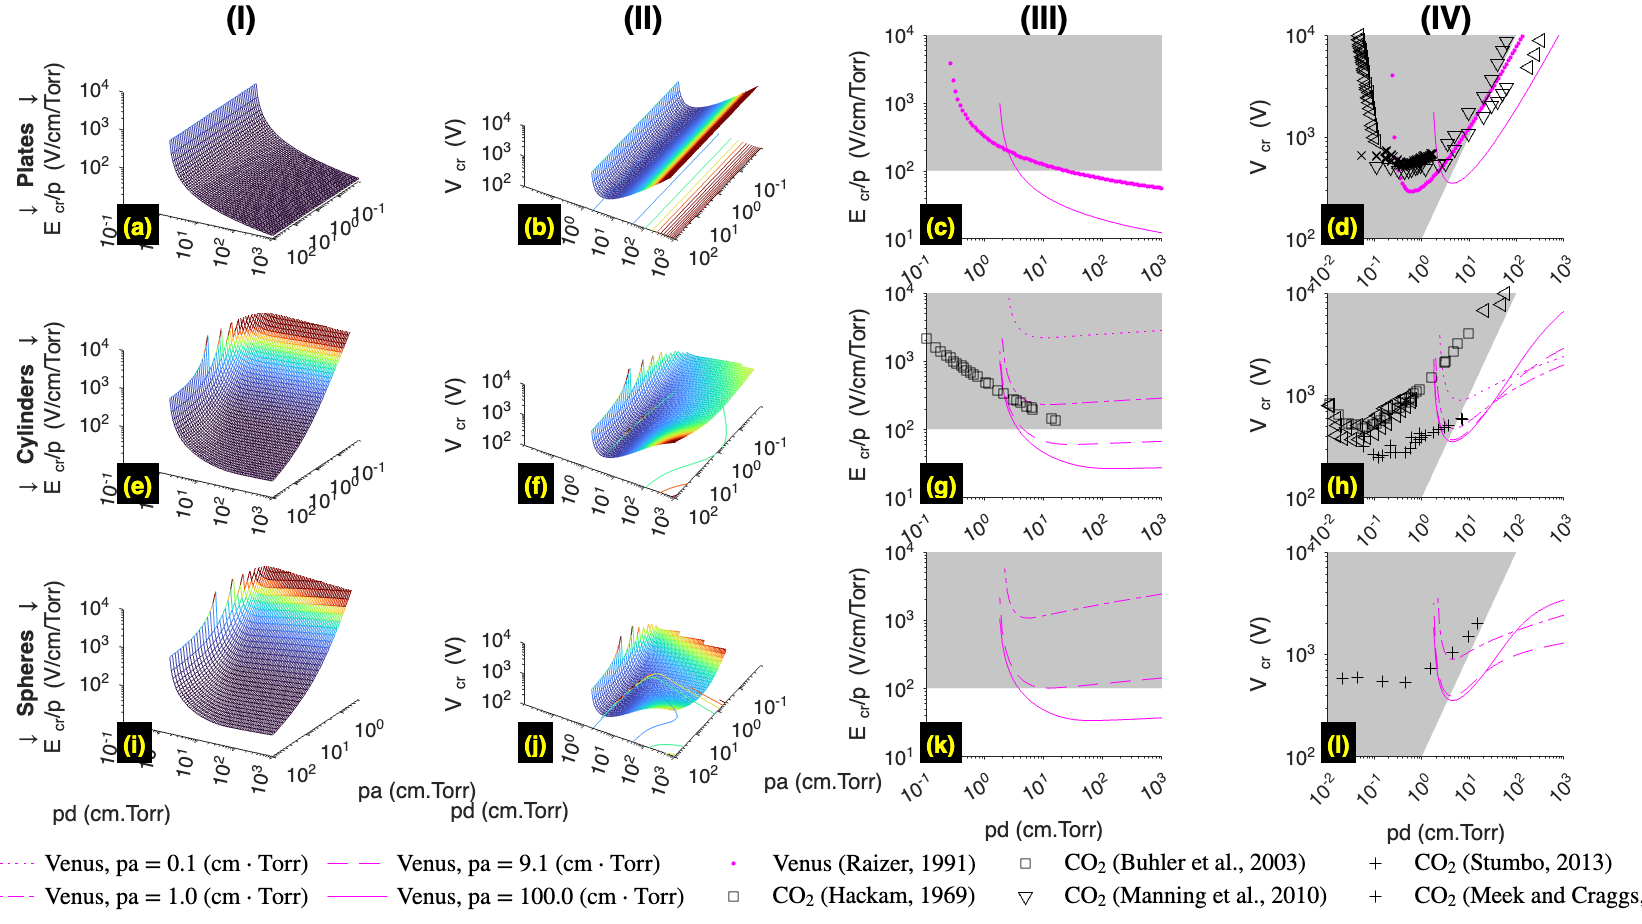

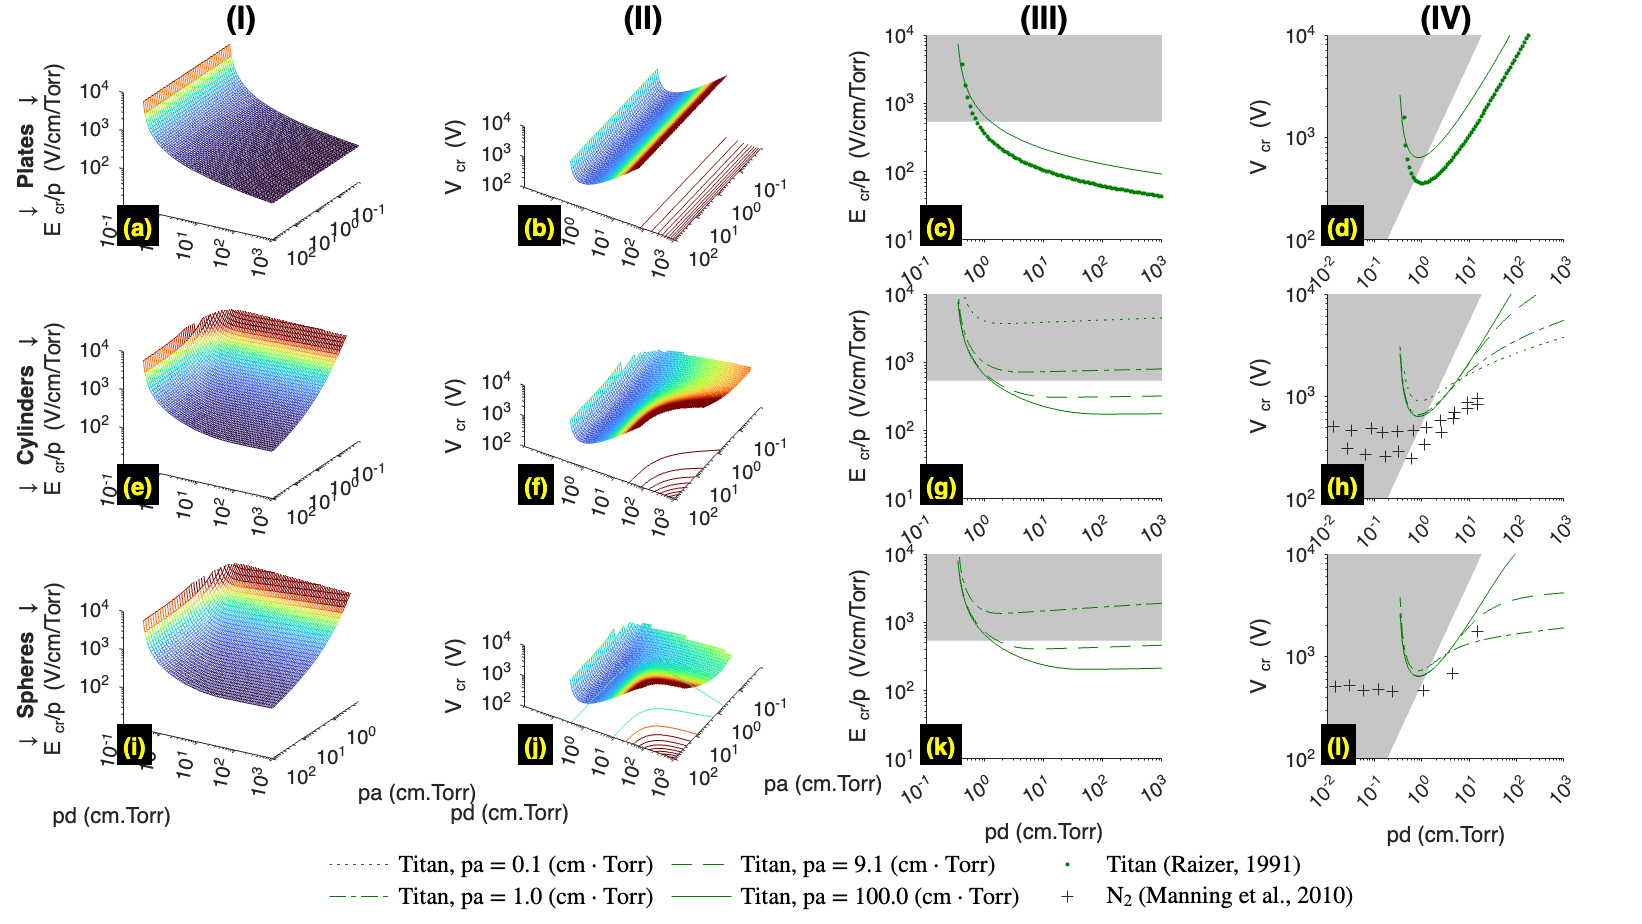

lgd = [];
for k=1:numel(P)
    lgd{k} = legend(hp{k});
    lgd{k}.NumColumns = 5;
    lgd{k}.Box = "off";
    lgd{k}.Interpreter = 'LaTeX';
    lgd{k}.Layout.Tile = "south";
    lgd{k}.FontSize = 12;

    for j = numel(lgd{k}.String):-1:1 % remove redundent legends
        if ismember(lgd{k}.String{j},lgd{k}.String(1:j-1))
            lgd{k}.String(j) = [];
        end
    end
end

## Export Figures

for k=1:numel(P)
    hf(k).PaperOrientation = 'landscape';
    hf(k).PaperUnits       = 'normalized';
    hf(k).PaperPosition    = [0 0 1 1];
    print(hf(k),'-dpdf',[P(k).name,'.pdf'],'-fillpage','-vector');
end